#### Part-1: Auto-correlation to determine hidden property (periodic or not) of a  signal

clc; clear all; close all;

duty = 50;                  % On-OFF time ratio of square wave
f = 4*10.^9;                % Frequency of the rectangular pulse
ti=1/f;                     % Time period 
s = ti/100;                 % sampling period
t = 0:s:8*ti;               % time range
x = square(2*pi*f*t,duty);  % The square wave

% Noise Components %
%a = 1; 
%b = -1;                     
% The noise varies in between -1 and 1
%N = (b-a).*rand(size(x,2),1) + a
%n = transpose(N);
n = awgn(x, 5, 'measured')

n =     0.8645    0.9677    0.1815    0.5913    1.2646    1.5517    0.7852    2.5808    0.1927   -0.0649    2.2985    0.2633    0.8498    0.2124    0.0679    0.3856    0.8706    0.6443    1.6888    0.6676    2.0081    0.3468   -0.2388    1.2342    2.0487    0.8151    1.9813    0.8066    0.4974    0.0163    1.8505   -0.0293    0.7409    0.3810    0.3858    0.7747    1.1138    1.1875    0.3292    1.2707    1.4091    0.8886    0.8195    0.0395    1.2465    2.3076    1.5951    0.9087    1.4579    1.1470


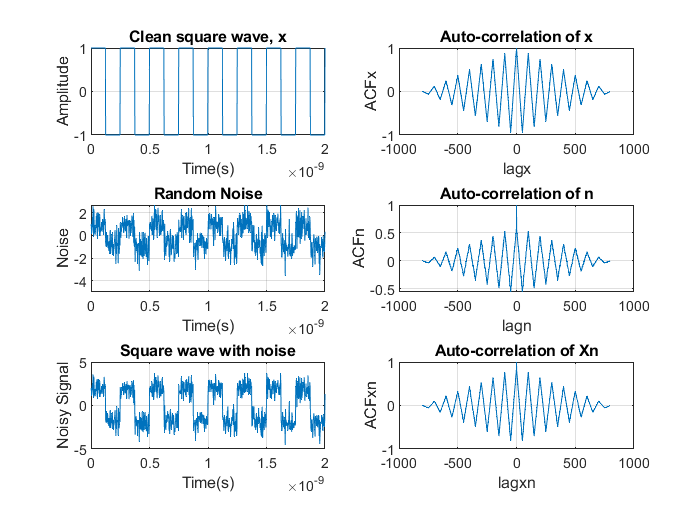

% Signal with Noise %
Xn = x+n;

% Auto-Correlation Function %
[ACFx,lagx] = xcorr(x,x,'coeff');
[ACFn,lagn] = xcorr(n,n,'coeff');
[ACFxn,lagxn] = xcorr(Xn,Xn,'coeff');

figure;
subplot(3,2,1)
plot(t,x)
title('Clean square wave, x')
xlabel('Time(s)')
ylabel('Amplitude')
grid on

subplot(3,2,3)
plot(t,n)
title('Random Noise')
xlabel('Time(s)')
ylabel('Noise')
grid on

subplot(3,2,5)
plot(t,Xn)
title('Square wave with noise')
xlabel('Time(s)')
ylabel('Noisy Signal')
grid on

subplot(3,2,2)
plot(lagx, ACFx)
title('Auto-correlation of x')
xlabel('lagx')
ylabel('ACFx')
grid on

subplot(3,2,4)
plot(lagn, ACFn)
title('Auto-correlation of n')
xlabel('lagn')
ylabel('ACFn')
grid on

subplot(3,2,6)
plot(lagxn, ACFxn)
title('Auto-correlation of Xn')
xlabel('lagxn')
ylabel('ACFxn')
grid on

#### Part-2: Cross-correlation in RADAR systems 

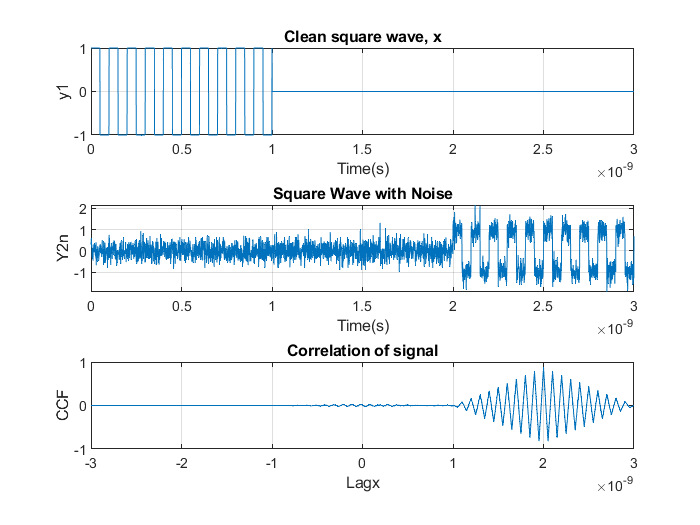

clc; clear all; close all;

duty = 50;                      % On-OFF time ratio of square wave
f = 10*10.^9;                   % Frequency of the square wave
ti = 1/f;                       % Time period 
s = ti/100;
t1 = 0:s:10*ti;                 % Total time
x1 = square(2*pi*f*t1,duty);    % The square wave
n1=t1/s;

% Delay the signal by 20*ti %
tdelay = 20*ti;
n0 = tdelay/(s);                % Shifting of t=6 second
[x2,n2] = sigshift(x1,n1,n0);
t2=n2*s;

min_n=min(min(n1),min(n2));
max_n=max(max(n1),max(n2));
n=min_n:max_n;
t=n*s;

y1=zeros(1,length(n));
y2=y1;
y1((n>=min(n1))&(n<=max(n1))==1)=x1;
y2((n>=min(n2))&(n<=max(n2))==1)=x2;
y2n=awgn(y2,5,'measured');

% Cross-correlation function %
[CCF,lagx] = xcorr(y2n,y1,'coeff');

figure;
subplot(3,1,1)
plot(t,y1)
title('Clean square wave, x')
xlabel('Time(s)')
ylabel('y1')
grid on

subplot(3,1,2)
plot(t,y2n)
title('Square Wave with Noise')
xlabel('Time(s)')
ylabel('Y2n')
grid on

subplot(3,1,3)
plot(lagx*s, CCF)
title('Correlation of signal')
xlabel('Lagx')
ylabel('CCF')
grid on

function [y,n]=sigshift(x,m,n0)
n=m+n0;
y=x;
end